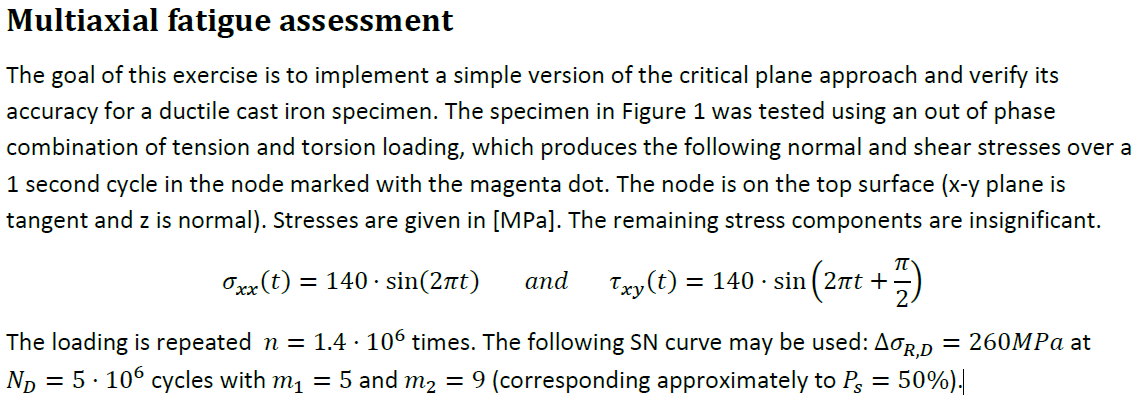

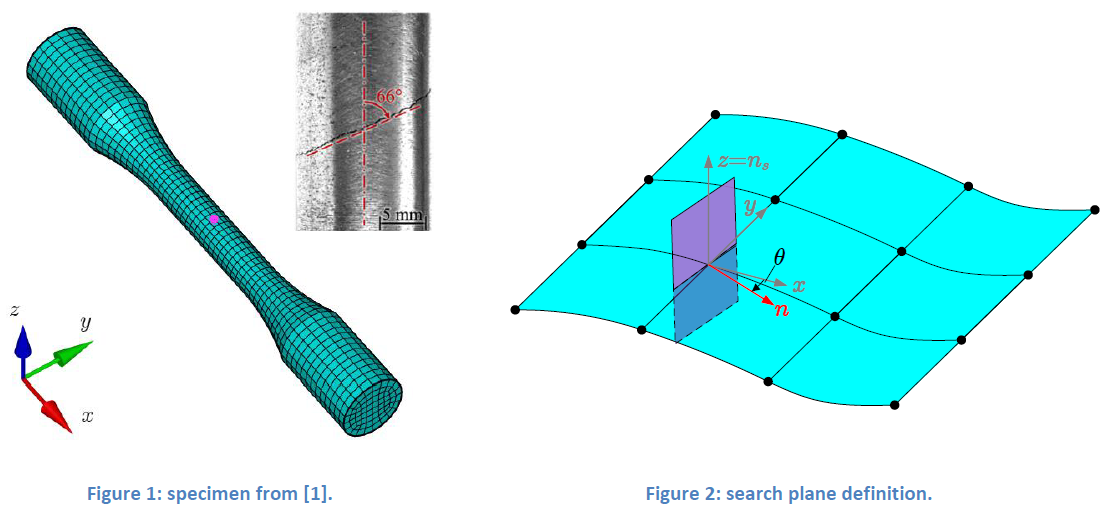

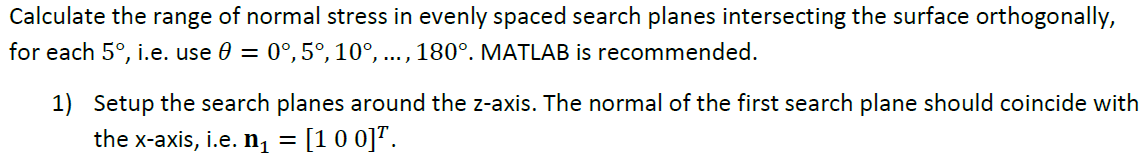

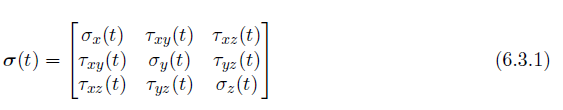

clear all
clf
deg = 5; %antal grader der skal roteres
theta = 0:deg:180-deg;
for i = 1:length(theta)
    n{i} = [cosd(theta(i)) sind(theta(i)) 0]';
end

t = 0:0.01:1;

for ti = 1:length(t)
    S_xx = 140 * sin(2*pi*t(ti));
    tau_xy = 140 * sin(2*pi*t(ti)+pi/2);
    S(:,:,ti) = [S_xx, tau_xy, 0
                tau_xy, 0, 0
                0, 0, 0];

    S_xx(ti) = 140 * sin(2*pi*t(ti));
    tau_xy(ti) = 140 * sin(2*pi*t(ti)+pi/2);
end

2) In each plane, calculate the normal stress over time and determine its range.

Vi finder den maximale sigma range før ved at trække den mindste fra den største i alle retningerne.

Derefter ved at finde den maximale i tiden.

for i = 1:length(theta)
    for j= 1:length(t)
    S_n(j) = n{i}' * S(:,:,j) * n{i};
    end
    dS_n(i) = max(S_n) - min(S_n);
end
dS_n_max = max(dS_n)

dS_n_max = 323.2984

3) Calculate and plot the damage in each search plane as a function of the angle 𝜃.

N_D = 5e6;
dS_D = 260;
n = 1.4e6;
m1 = 5;
m2 = 9;

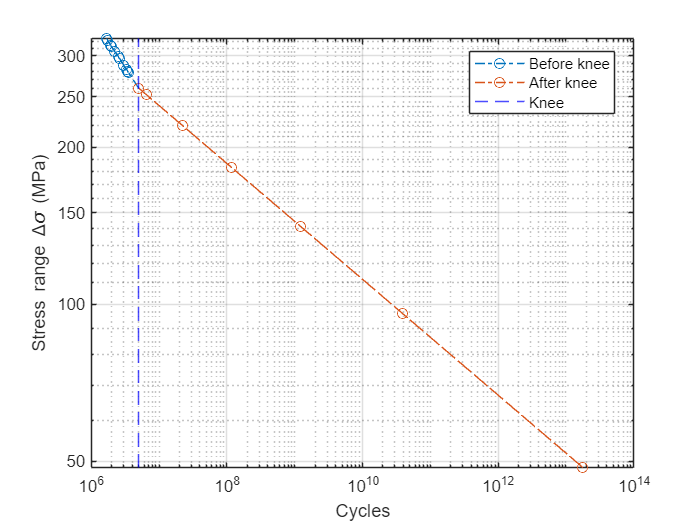

C1 = dS_D^m1 * N_D;
C2 = dS_D^m2 * N_D;
N_1 = [];
N_2 = [];
dS_1 = [];
dS_2 = [];
Ds1 = [];
Ds2 = [];
for i = 1:length(dS_n)
    if dS_n(i) > dS_D
        N_1(end +1) = C1 / dS_n(i)^m1; %finder et punkt for S_1 med vores maximale lokal spænding
        dS_1(end +1) = dS_n(i);
        Ds1(end +1) = 1/N_1(end); %damge
        Ds(i) = Ds1(end);
    else
        N_2(end +1) = C2 / dS_n(i)^m2;
        dS_2(end +1) = dS_n(i);
        Ds2(end +1) = 1/N_2(end); %damge
        Ds(i) = Ds2(end);
    end
    
end
N_1_plot = [N_1, N_D];
N_2_plot = [N_D, N_2];
dS_1_plot = [dS_1, dS_D];
dS_2_plot = [dS_D, dS_2];

figure(2)
loglog(N_1_plot,dS_1_plot,'o-.', 'DisplayName','Before knee')%, "filled")
hold on
loglog(N_2_plot,dS_2_plot,'o-.', 'DisplayName','After knee')%, "filled")
xline(N_D,'b--', 'DisplayName','Knee')
xlabel('Cycles')
ylabel('Stress range \Delta\sigma (MPa)')
grid("on")
legend(Location='best')
hold off

Damage at number of cycles

% for i = 1:length(dS_n)
%     if dS_n(i) > dS_D
%         N_1(end +1) = C1 / dS_n(i)^m1; %finder et punkt for S_1 med vores maximale lokal spænding
%         dS_1(end +1) = dS_n(i);
%     else
%         N_2(end +1) = C2 / dS_n(i)^m2;
%         dS_2(end +1) = dS_n(i);
%     end
% end
% N_1_plot = [N_1, N_D];
% N_2_plot = [N_D, N_2];
% dS_1_plot = [dS_1, dS_D];
% dS_2_plot = [dS_D, dS_2];
% 
% loglog(N_1_plot,dS_1_plot,'o-.', 'DisplayName','Before knee')%, "filled")
% hold on
% loglog(N_2_plot,dS_2_plot,'o-.', 'DisplayName','After knee')%, "filled")
% xline(N_D,'b--', 'DisplayName','Knee')
% xlabel('Cycles')
% ylabel('Stress range \Delta\sigma (MPa)')
% grid("on")
% legend(Location='best')
% hold off

D_1sek = sum(Ds)

D_1sek = 1.0532e-05

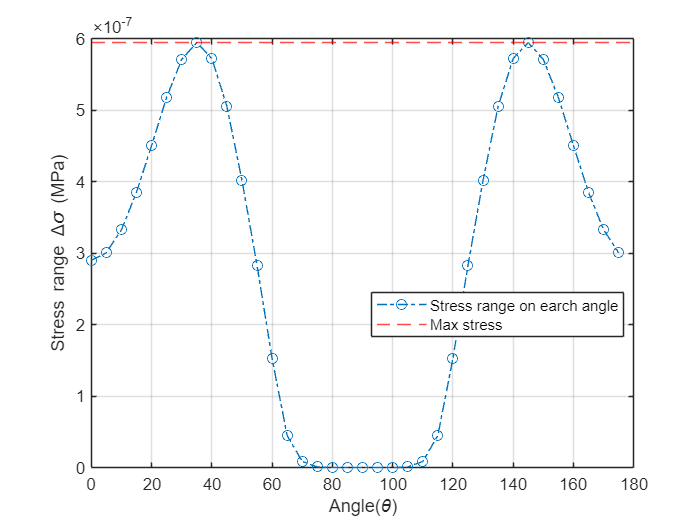

figure(1)
plot(theta, Ds, 'o-.', 'DisplayName','Stress range on earch angle ') %dS_n
yline(max(Ds), 'r--', 'DisplayName','Max stress ')
xlabel('Angle(\theta)')
ylabel('Stress range \Delta\sigma (MPa)')
grid("on")
legend(Location='best')
hold off

4) Determine the angle of the critical plane and compare it with that of the experiment (66°).

find_D_max = find(Ds==max(Ds))

find_D_max = 8

theta_critical = theta(find_D_max)

theta_critical = 35

5) If time allows, try the same analysis in Fatlab. Input files can be download here:

https://sourceforge.net/projects/fatlab/files/benchmarks/Multiaxial%20fatigue.zip

The loads file Loads_out-of-phase.xlsx corresponds to this exercise. Use node 2979.